## Interpolate sine data

ws = logspace(.7,2,20)

ws =     5.0119    5.8671    6.8682    8.0401    9.4120   11.0181   12.8981   15.0990   17.6754   20.6914   24.2220   28.3551   33.1935   38.8574   45.4878   53.2495   62.3357   72.9723   85.4238  100.0000


indx = 20;

w = ws(indx);
fileName = sprintf("./pd_freq_response/freq_response_%d.mat",indx)

fileName = "./pd_freq_response/freq_response_20.mat"


load(fileName);


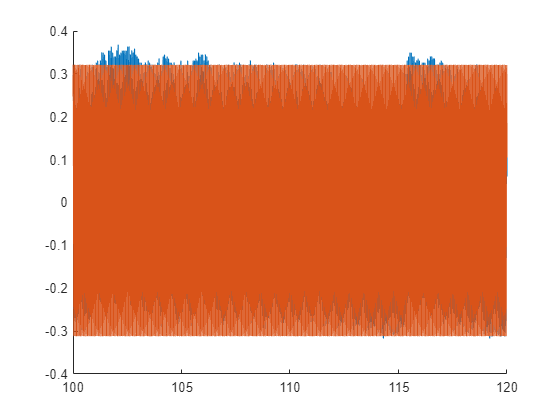

figure();
hold on;
plot(x_res.time,x_res.signals.values);

sinDta = interpolateSineData(x_res.time,x_res.signals.values,w);

interpolatedSine = sinDta.U*sin(w*x_res.time+sinDta.Phi)+sinDta.M;

plot(x_res.time,interpolatedSine);

## Plotting response


U_data = zeros(length(ws),3);
for i = 1:length(ws)
    w_i = ws(i);
    file_i = sprintf("./pd_freq_response/freq_response_%d.mat",i);

    load(file_i);

    sinDta = interpolateSineData(x_res.time,x_res.signals.values,w_i);

    U_data(i,1) = ws(i); U_data(i,2) = 20*log10(abs(sineData.U)/U_in); U_data(i,3) = rad2deg(sineData.Phi);

end

load("pd_parameters.mat");
%ws = logspace(-3,3);
j = sqrt(-1);
G_jw = @(w) (pd_param.Kp + pd_param.Kd*(pd_param.a*j*w)/(j*w + pd_param.a))*(1/(m*(j*w)^2 + b*(j*w)));
U_data

U_data =     5.0119  -11.9551 -147.8700
    5.8671  -11.9274 -147.8700
    6.8682  -11.8899 -147.8700
    8.0401  -11.8393 -147.8700
    9.4120  -11.7714 -147.8700
   11.0181  -11.6809 -147.8700
   12.8981  -11.5615 -147.8700
   15.0990  -11.4060 -147.8700
   17.6754  -11.2064 -147.8700
   20.6914  -10.9555 -147.8700


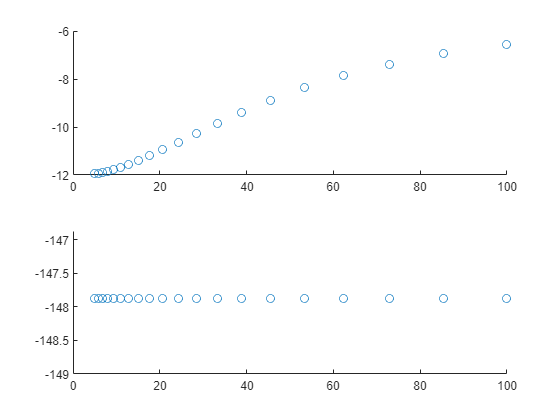

figure();
subplot(2,1,1)
hold on;
% %loglog(U_data(:,1),U_data(:,2),'o')\
% for i = length(ws)
%     Us(i) = 20*log10(abs(G_jw(ws(i))));
% end
loglog(ws,U_data(:,2),'o');

subplot(2,1,2)
hold on;
semilogx(ws,U_data(:,3),'o');

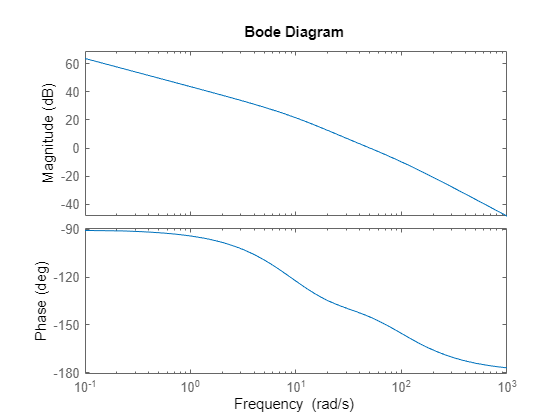

figure();
s = tf("s");
G_s = (pd_param.Kp + pd_param.Kd*(pd_param.a*s)/(s+pd_param.a))*(1/(m*s^2 + b*s));
bode(G_s)